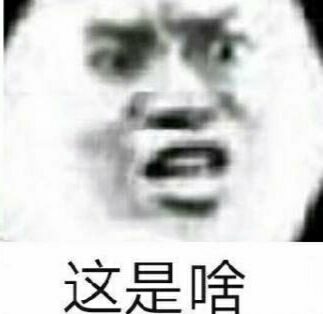

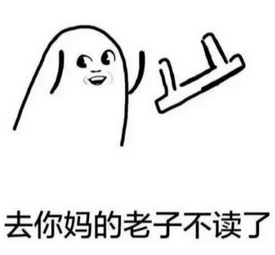

第三题,二分法还原答案结果

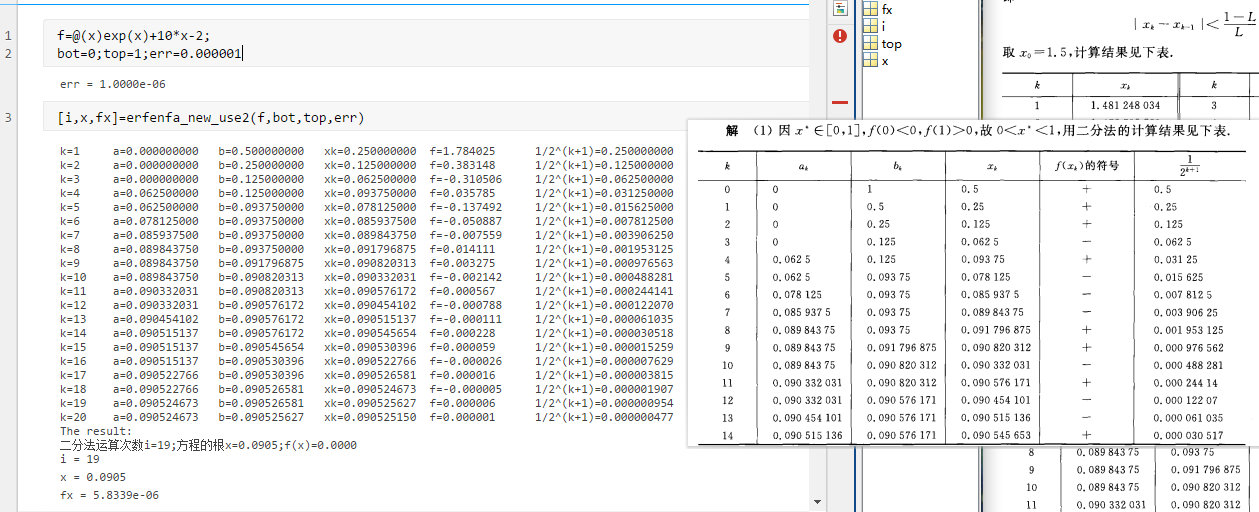

f=@(x)exp(x)+10*x-3;
bot=0;top=1;err=0.000001

err = 1.0000e-06

[i,x,fx]=erfenfa_new_use2(f,bot,top,err)


k=1	a=0.000000000	b=0.500000000	xk=0.250000000	f=0.784025	1/2^(k+1)=0.250000000
k=2	a=0.000000000	b=0.250000000	xk=0.125000000	f=-0.616852	1/2^(k+1)=0.125000000
k=3	a=0.125000000	b=0.250000000	xk=0.187500000	f=0.081230	1/2^(k+1)=0.062500000
k=4	a=0.125000000	b=0.187500000	xk=0.156250000	f=-0.268382	1/2^(k+1)=0.031250000
k=5	a=0.156250000	b=0.187500000	xk=0.171875000	f=-0.093721	1/2^(k+1)=0.015625000
k=6	a=0.171875000	b=0.187500000	xk=0.179687500	f=-0.006282	1/2^(k+1)=0.007812500
k=7	a=0.179687500	b=0.187500000	xk=0.183593750	f=0.037465	1/2^(k+1)=0.003906250
k=8	a=0.179687500	b=0.183593750	xk=0.181640625	f=0.015589	1/2^(k+1)=0.001953125
k=9	a=0.179687500	b=0.181640625	xk=0.180664063	f=0.004653	1/2^(k+1)=0.000976563
k=10	a=0.179687500	b=0.180664063	xk=0.180175781	f=-0.000814	1/2^(k+1)=0.000488281
k=11	a=0.180175781	b=0.180664063	xk=0.180419922	f=0.001919	1/2^(k+1)=0.000244141
k=12	a=0.180175781	b=0.180419922	xk=0.180297852	f=0.000553	1/2^(k+1)=0.000122070
k=13	a=0.180175781	b=0.18029785

i = 19

x = 0.1802

fx = 7.9056e-06

第七题

第二小问可以用卡西欧991完成

附上参考链接:

[https://www.zhihu.com/question/323716445](https://www.zhihu.com/question/323716445)

第三小问

向社会分子低头,我选择计算机

f=@(x)x.^3-3.*x-1

f = 包含以下值的 function_handle :
    @(x)x.^3-3.*x-1


x=zeros(6,1);
x(1)=1;x(2)=3;x(3)=2;%初始化x,并且输入x0,x1,x2

计算x0,x1,x2差商,从而得到ω

k=3;
A=csb(x(k-2:k),f(x(k-2:k)))

A =      1    -3     0     0
     3    17    10     0
     2     1    16     6


omega=A(3,3)+A(3,4)*(A(3,1)-A(2,1));
fprintf("k=%d时omega=%f+%f*%f=%f",k,A(3,3),A(3,4),A(3,1)-A(2,1),omega)

k=3时omega=16.000000+6.000000*-1.000000=10.000000

x(k+1)=x(k)-2*f(x(k))/(omega+sign(omega)*sqrt(omega^2-4*f(x(k))*A(3,4)));
fprintf("x_%d=%.9f",k,x(k+1))

x_3=1.893149824

k=4;
A=csb(x(k-2:k),f(x(k-2:k)))

A =     3.0000   17.0000         0         0
    2.0000    1.0000   16.0000         0
    1.8931    0.1056    8.3703    6.8931


omega=A(3,3)+A(3,4)*(A(3,1)-A(2,1));
fprintf("k=%d时omega=%f+%f*%f=%f",k,A(3,3),A(3,4),A(3,1)-A(3,2),omega)

k=4时omega=8.370316+6.893150*1.787520=7.633782

x(k+1)=x(k)-2*f(x(k))/(omega+sign(omega)*sqrt(omega^2-4*f(x(k))*A(3,4)));
fprintf("x_%d=%.9f",k,x(k+1))

x_4=1.879135257

k=5;
A=csb(x(k-2:k),f(x(k-2:k)))

A =     2.0000    1.0000         0         0
    1.8931    0.1056    8.3703         0
    1.8791   -0.0019    7.6727    5.7723


omega=A(3,3)+A(3,4)*(A(3,1)-A(2,1));
fprintf("k=%d时omega=%f+%f*%f=%f",k,A(3,3),A(3,4),A(3,1)-A(3,2),omega)

k=5时omega=7.672650+5.772285*1.881034=7.591754

x(k+1)=x(k)-2*f(x(k))/(omega+sign(omega)*sqrt(omega^2-4*f(x(k))*A(3,4)));
fprintf("x_%d=%.9f",k,x(k+1))

x_5=1.879385296

第八题

clc;clear;
f=@(x)2*x-tan(x);
bot=4;top=4.7;err=0.00000001

err = 1.0000e-08

[i,x,fx]=erfenfa_new_use2(f,bot,top,err)


k=1	a=4.350000000	b=4.700000000	xk=4.525000000	f=3.776117	1/2^(k+1)=0.250000000
k=2	a=4.525000000	b=4.700000000	xk=4.612500000	f=-0.752796	1/2^(k+1)=0.125000000
k=3	a=4.525000000	b=4.612500000	xk=4.568750000	f=2.223547	1/2^(k+1)=0.062500000
k=4	a=4.568750000	b=4.612500000	xk=4.590625000	f=1.009269	1/2^(k+1)=0.031250000
k=5	a=4.590625000	b=4.612500000	xk=4.601562500	f=0.216983	1/2^(k+1)=0.015625000
k=6	a=4.601562500	b=4.612500000	xk=4.607031250	f=-0.242265	1/2^(k+1)=0.007812500
k=7	a=4.601562500	b=4.607031250	xk=4.604296875	f=-0.006717	1/2^(k+1)=0.003906250
k=8	a=4.601562500	b=4.604296875	xk=4.602929688	f=0.106559	1/2^(k+1)=0.001953125
k=9	a=4.602929688	b=4.604296875	xk=4.603613281	f=0.050284	1/2^(k+1)=0.000976563
k=10	a=4.603613281	b=4.604296875	xk=4.603955078	f=0.021875	1/2^(k+1)=0.000488281
k=11	a=4.603955078	b=4.604296875	xk=4.604125977	f=0.007602	1/2^(k+1)=0.000244141
k=12	a=4.604125977	b=4.604296875	xk=4.604211426	f=0.000448	1/2^(k+1)=0.000122070
k=13	a=4.604211426	b=4.604296875	

i = 26

x = 4.6042

fx = -4.0247e-07

function [i,x,fx]=erfenfa_new_use2(f,bot,top,err)
%输入：f为要求解的方程函数表达式，bot为求解区间的下界，top为求解区间的上界，err为所要求的误差范围
%输出：i为二分法求解的次数，x为最终的根，fx为方程的根x对应的函数值（精度要求内接近于零或等于零）
if f(bot)*f(top)>0
    disp('\n注意：f(bot)*f(top)>0,无法继续运算，请重新调整区间端点bot和top.\n');
    return
end
i=ceil((log(top-bot)- log(err))/log(2))-1; %n为二分法运算总的次数；ceil是上取整 ,相对应的floor是下取整
k=0;
while abs(top-bot)>err
    
    x=(bot+top)/2;
    fx=f(x);
    if fx==0
        bot=x; top=x;
    elseif f(bot)*fx<0
        top=x;
    else
        bot=x;
    end
    k=k+1;
    fprintf('\nk=%d\ta=%.9f\tb=%.9f\txk=%.9f\tf=%f\t1/2^(k+1)=%.9f',k,bot,top,(bot+top)/2,f((bot+top)/2),1/2^(k+1))
end
fprintf('\nThe result:\n二分法运算次数i=%d;方程的根x=%.4f;f(x)=%.4f\n',i,x,fx);%保留4位小数
end

function A=csb(X,Y)
n=length(X);
A=zeros(n,n+1);
A(:,1)=X';
A(:,2)=Y';
for j=3:n+1
for i=j-1:n
A(i,j)=(A(i,j-1)-A(i-1,j-1))./(A(i,1)-A(i-j+2,1));
end
end
end